clear; close all
cd('/Users/cansu/Documents/GitHub/Permafrost_ERRA/rawdata')

file_goose = 'CB_thawingdepth_daily.txt';
file_ptarmigan = 'CB_thawingdepth_dist_daily.txt';
printfig = true;
workdirfig = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/rawdata/Timeseries/figures';  % or specify desired folder for saving

% Load data
data_goose = readtable(file_goose);
data_ptarmigan = readtable(file_ptarmigan);

% Define winter months (e.g. Dec, Jan, Feb)
winterMonths = [10, 11, 12, 1, 2, 3, 4, 5];

% Find rows corresponding to winter months
isWinter_g = ismember(data_goose.months, winterMonths);
isWinter_p = ismember(data_ptarmigan.months, winterMonths);

% Set P to NaN for those rows
data_goose.P(isWinter_g) = NaN;
data_ptarmigan.P(isWinter_p) = NaN;

time_goose = data_goose.time_cont;
time_ptarmigan = data_ptarmigan.time_cont;

% Color settings
color_precip = [0, 0, 0];           % black
color_discharge = [0, 0, 1];              % blue
color_ptarmigan = [217, 95, 2]/255;
color_goose = [27, 158, 119]/255;

% Plot formatting
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2*3};
FS = {'FontSize',10*3,15*3,18*3,21*3,24*3};
UN = {'Units','Normalized','Inches'};
MS = {'MarkerSize',30,50,100};

axh = 5; axw = 2.5*axh;
ahs = 0.15; avs = 0.15;
axb = 1.3; axt = 0.9; axl = 1.7; axr = 1.1;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + axh + avs + ht + axt;
fw = axl + axw + ahs + cbw + axr;

format = '-dpng'; resl = '-r200'; rend = '-opengl';


createLongFig = @(name) ...
    set(figure('Name',name), 'Units','Inches','Position',[0.7 12 fw fh], ...
    'PaperPosition',[0 0 fw*2.2 fh*2.2], 'PaperSize',[fw fh], ...
    'Color','w','InvertHardcopy','off','MenuBar','none','Resize','off','Toolbar','none');

f1 = createLongFig('Precip and Q');
ax = axes('Units','Inches','position',[axl axb axw axh]);

hold on 

yyaxis right

x_patch = [2007.5, 2012, 2012, 2007.5];
yl = [min(data_goose.Q), 20]

yl =      0    20


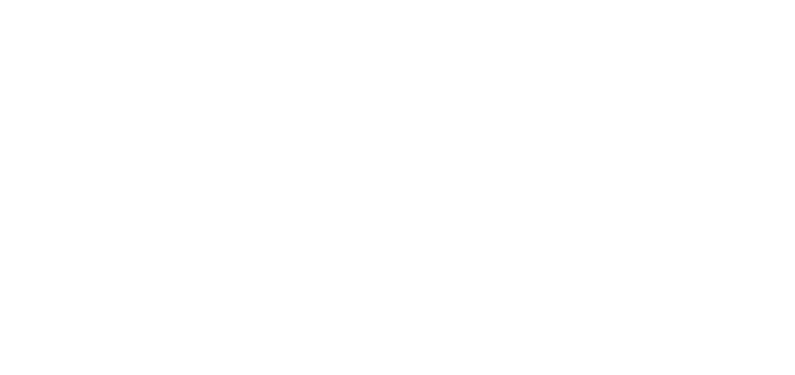

y_patch = [yl(1), yl(1), yl(2), yl(2)];
h_patch = fill(x_patch, y_patch, [153,52,4]./255, 'FaceAlpha', 0.5, 'EdgeColor', 'none','HandleVisibility', 'off');
drawnow;  % Ensures the graphics object is registered
uistack(h_patch, 'bottom');
text(2009.4, yl(2).*1.05, {'ALDS Activity'}, ...
     'Color', [0.3 0.3 0.3], FS{[1,5]}, TX{:}, ...
     'HorizontalAlignment', 'center');

hold on


yyaxis left
h2 = plot(time_goose, data_goose.P, '-', 'Color', color_precip, 'LineWidth', 20); 
ylabel('Precipitation [mm/d]', TX{:}, FS{[1,5]}, UN{[1,3]});
set(gca, 'YColor', color_precip);  % Set y-axis color for right axis


yyaxis right
plot(time_goose, data_goose.Q, '-', 'Color', color_discharge, 'LineWidth', 20);
ylabel('Discharge [mm/d]', TX{:}, FS{[1,5]}, UN{[1,3]});
set(gca, 'YColor', color_discharge);  % Set y-axis color for left axis


xlabel('Time (decimal year)', TX{:}, FS{[1,5]}, UN{[1,3]});
set(gca, TL{:}, LW{[1,4]}, FS{[1,5]});



if printfig
    cd(workdirfig);
    print(f1, format, resl, rend, 'CB_Precip_Discharge', '-loose');
end


vars = {'DOC', 'TDS', 'SS', 'POC'};
titles = {'DOC Time Series', 'TDS Time Series', 'SSC Time Series', 'POC Time Series'};

for i = 1:numel(vars)
    v = vars{i};
    t = titles{i};

    f = createLongFig(t);
    ax = axes('Units','Inches','position',[axl axb axw axh]);
    hold on

    plot(time_ptarmigan, data_ptarmigan.(v).*data_ptarmigan.Q/100, '-', 'Color', color_ptarmigan, 'LineWidth', 4);
    plot(time_goose, data_goose.(v).*data_goose.Q/100, '-', 'Color', color_goose, 'LineWidth', 4);
    yl = ylim;

    x_patch = [2007.5, 2012, 2012, 2007.5];
    % yl = [min([min(data_ptarmigan.(v).*data_ptarmigan.Q),min(data_goose.(v).*data_goose.Q)]); max([max(data_ptarmigan.(v).*data_ptarmigan.Q),max(data_goose.(v).*data_goose.Q)])]
    y_patch = [yl(1), yl(1), yl(2), yl(2)];
    h_patch = fill(x_patch, y_patch, [153,52,4]./255, 'FaceAlpha', 0.5, 'EdgeColor', 'none');
    text(2009.4, yl(2).*1.05, {'ALDS Activity'}, ...
         'Color', [0.3 0.3 0.3], FS{[1,5]}, TX{:}, ...
         'HorizontalAlignment', 'center');

   
    plot(time_ptarmigan, data_ptarmigan.(v).*data_ptarmigan.Q/100, '-', 'Color', color_ptarmigan, 'LineWidth', 20);
    plot(time_goose, data_goose.(v).*data_goose.Q/100, '-', 'Color', color_goose, 'LineWidth', 20);

   

    xlabel('Time (decimal year)', TX{:}, FS{[1,5]}, UN{[1,3]});
    ylabel(sprintf('%s flux [(dg)/(m$^2$ d)]', v), TX{:}, FS{[1,5]}, UN{[1,3]});

    [lgd, hobj, ~, ~] = legend('Ptarmigan', 'Goose', 'Location', 'northeast', TX{:}, FS{[1,2]});
    adjustLegendSize(lgd,hobj,1.05,1.00,10,1);
    set(gca, TL{:}, LW{[1,4]}, FS{[1,5]});


    if printfig
        cd(workdirfig);
        print(f, format, resl, rend, ['CB_', v, '_TimeSeries'], '-loose');
    end
end

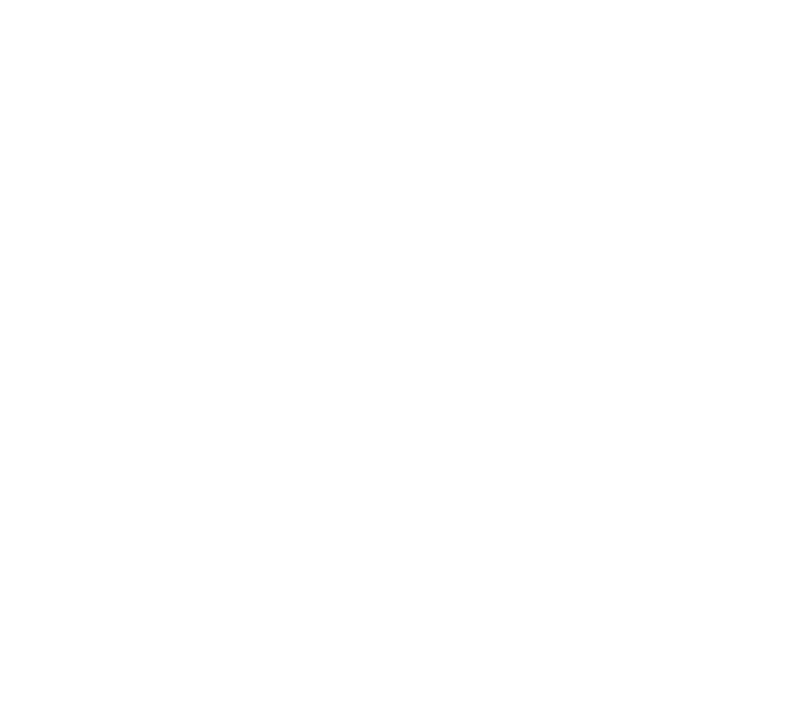


axh = 5; axw = axh;
ahs = 0.15; avs = 0.15;
axb = 1.3; axt = 0.9; axl = 1.7; axr = 1.1;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + axh + avs + ht + axt;
fw = axl + axw + ahs + cbw + axr;


createSquareFig = @(name) ...
    set(figure('Name',name), 'Units','Inches','Position',[0.7 12 fw fh], ...
    'PaperPosition',[0 0 fw*2.2 fh*2.2], 'PaperSize',[fw fh], ...
    'Color','w','InvertHardcopy','off','MenuBar','none','Resize','off','Toolbar','none');


vars = {'DOC', 'TDS', 'SS', 'POC'};        
xvars = {'Q', 'P'};                       
xlabels = {'Discharge [mm/d]', 'Precipitation [mm/d]'};
xtags   = {'Q', 'P'};
printfig   = true;    
workdirfig = pwd;
format     = '-dpng'; resl = []; rend = [];

for i = 1:numel(vars)
    v      = vars{i};
    vlabel = sprintf('%s flux [(dg)/(m$^2$ d)]', v);

    for j = 1:numel(xvars)
        xvar = xvars{j};
        xlab = xlabels{j};
        xtag = xtags{j};

        f  = createSquareFig([v ' vs ' xvar]);
        ax = axes('Units','Inches','Position',[axl axb axw axh]);
        hold on

        % calculate flux (conc * Q) and pull x-data
        x_pt   = data_ptarmigan.(xvar);
        x_go   = data_goose.(xvar);
        flux_pt = data_ptarmigan.(v) .* data_ptarmigan.Q / 100;
        flux_go = data_goose.(v)     .* data_goose.Q     / 100;

        mask_pt = ~isnan(x_pt) & ~isnan(flux_pt);
        mask_go = ~isnan(x_go) & ~isnan(flux_go);
        x_pt2   = x_pt(mask_pt);
        x_go2   = x_go(mask_go);
        flux_pt2 = flux_pt(mask_pt);
        flux_go2 = flux_go(mask_go);



        h_sc_pt = scatter(x_pt2, flux_pt2, 150, 'filled', 'MarkerFaceColor', color_ptarmigan);
        h_sc_go = scatter(x_go2, flux_go2, 150, 'filled', 'MarkerFaceColor', color_goose);

        % compute Spearman's rho
        [rho_pt, p_pt] = corr(x_pt2, flux_pt2, 'Type','Spearman', 'Rows','complete');
        [rho_go, p_go] = corr(x_go2, flux_go2, 'Type','Spearman', 'Rows','complete');

        coef_pt = polyfit(x_pt2, flux_pt2, 1);
        coef_go = polyfit(x_go2, flux_go2, 1);

        xfit_pt = linspace(min(x_pt2), max(x_pt2), 100);
        yfit_pt = coef_pt(1) * xfit_pt + coef_pt(2);
        xfit_go = linspace(min(x_go2), max(x_go2), 100);
        yfit_go = coef_go(1) * xfit_go + coef_go(2);


        h_fit_pt = plot(xfit_pt, yfit_pt, 'LineWidth', 5, 'Color', color_ptarmigan);
        h_fit_go = plot(xfit_go, yfit_go, 'LineWidth', 5, 'Color', color_goose);

        xlabel(xlab, TX{:}, FS{[1,5]}, UN{[1,3]});
        ylabel(vlabel, TX{:}, FS{[1,5]}, UN{[1,3]});
        set(gca, TL{:}, LW{[1,4]}, FS{[1,5]});
        grid off
        yl = ylim;                     % current [ymin ymax]
        set(gca, 'YLim', [yl(1), yl(2)*1.5]);


        [lgd, hobj, ~, ~] = legend( ...
          [h_fit_pt, h_fit_go], ... %h_sc_pt, h_sc_go, 
          { %'Ptarmigan data', ...
            %'Goose      data'  ...
            sprintf('Ptarmigan fit ($\\rho =$ %.2f)', rho_pt), ...
            sprintf('Goose fit ($\\rho =$ %.2f)', rho_go), ...

          }, ...
          'Location','northeast', TX{:}, FS{[1,5]});
        adjustLegendSize(lgd,hobj,1.05,1.00,10,1);
        lgd.ItemTokenSize = [50 50];   
        hold off


        if printfig
            cd(workdirfig);
            print(f, format, resl, rend, ['CB_' v '_vs_' xtag], '-loose');
        end
    end
end

axh = 5; axw = axh;
ahs = 0.15; avs = 0.15;
axb = 1.3; axt = 0.9; axl = 1.7; axr = 1.1;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + axh + avs + ht + axt;
fw = axl + axw + ahs + cbw + axr;


createSquareFig = @(name) ...
    set(figure('Name',name), 'Units','Inches','Position',[0.7 12 fw fh], ...
    'PaperPosition',[0 0 fw*2.2 fh*2.2], 'PaperSize',[fw fh], ...
    'Color','w','InvertHardcopy','off','MenuBar','none','Resize','off','Toolbar','none');


vars = {'SS', 'POC'};        
xvars = {'Q', 'P'};                       
xlabels = {'Discharge [mm/d]', 'Precipitation [mm/d]'};
xtags   = {'Q', 'P'};
printfig   = true;    
workdirfig = pwd;
format     = '-dpng'; resl = []; rend = [];


for i = 1:numel(vars)
    v      = vars{i};
    vlabel = sprintf('%s flux [(dg)/(m$^2$ d)]', v);

    for j = 1:numel(xvars)
        xvar = xvars{j};
        xlab = xlabels{j};
        xtag = xtags{j};

        % create figure + axes
        f  = createSquareFig([v ' vs ' xvar]);
        ax = axes('Units','Inches','Position',[axl axb axw axh]);
        hold on

        x_go   = data_goose.(xvar);
        flux_go = data_goose.(v)     .* data_goose.Q     / 100;

        mask_go = ~isnan(x_go) & ~isnan(flux_go);
        x_go2   = x_go(mask_go);
       flux_go2 = flux_go(mask_go);


        h_sc_go = scatter(x_go2, flux_go2, 150, 'filled', 'MarkerFaceColor', color_goose);

        % compute Spearman's rho
        [rho_go, p_go] = corr(x_go2, flux_go2, 'Type','Spearman', 'Rows','complete');

        % linear fit (for visualization)
        coef_go = polyfit(x_go2, flux_go2, 1);

        xfit_go = linspace(min(x_go2), max(x_go2), 100);
        yfit_go = coef_go(1) * xfit_go + coef_go(2);

        % plot fit lines
        h_fit_go = plot(xfit_go, yfit_go, 'LineWidth', 5, 'Color', color_goose);

        % labels & styling
        xlabel(xlab, TX{:}, FS{[1,6]}, UN{[1,3]});
        ylabel(vlabel, TX{:}, FS{[1,6]}, UN{[1,3]});
        set(gca, TL{:}, LW{[1,4]}, FS{[1,6]});
        grid off
        yl = ylim;                     % current [ymin ymax]
        % set(gca, 'YLim', [yl(1), yl(2)*1.5]);
        % legend with Spearman rho
        % [lgd, hobj, ~, ~] = legend( ...
        %   [h_sc_go, h_fit_go], ...
        %   { 'Goose      data'  ...
        %     sprintf('Goose fit ($\\rho =$ %.2f)', rho_go), ...
        % 
        %   }, ...
        %   'Location','northeast', TX{:}, FS{[1,6]});

        % adjustLegendSize(lgd,hobj,1.05,1.00,10,1);
        % lgd.ItemTokenSize = [50 50];   % [width height] in pixels

        hold off


        if printfig
            cd(workdirfig);
            print(f, format, resl, rend, ['Goose_' v '_vs_' xtag], '-loose');
        end
    end
end


axh = 5; axw = axh;
ahs = 0.15; avs = 0.15;
axb = 1.3; axt = 0.9; axl = 1.7; axr = 1.1;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + axh + avs + ht + axt;
fw = axl + axw + ahs + cbw + axr;


createSquareFig = @(name) ...
    set(figure('Name',name), 'Units','Inches','Position',[0.7 12 fw fh], ...
    'PaperPosition',[0 0 fw*2.2 fh*2.2], 'PaperSize',[fw fh], ...
    'Color','w','InvertHardcopy','off','MenuBar','none','Resize','off','Toolbar','none');


vars = {'DOC', 'TDS', 'SS', 'POC'};
xvars = {'Q'};                           
xlabels = {'Discharge [mm/d]'};
xtags   = {'Q'};
printfig   = true;                     
workdirfig = pwd;
format     = '-dpng'; resl = []; rend = [];


for i = 1:numel(vars)
    v      = vars{i};
    vlabel = sprintf('%s con. [(mg)/(L)]', v);

    for j = 1:numel(xvars)
        xvar = xvars{j};
        xlab = xlabels{j};

        f  = createSquareFig([v ' vs ' xvar]);
        ax = axes('Units','Inches','Position',[axl axb axw axh]);
        hold on

        x_pt = data_ptarmigan.(xvar);
        x_go = data_goose.(xvar);
        y_pt = data_ptarmigan.(v);
        y_go = data_goose.(v);

        
        
        % --- subset to strictly positive x & y values ---
        ok_pt = x_pt>0  & y_pt>0;
        ok_go = x_go>0  & y_go>0;
        
        x_pt2 = x_pt(ok_pt);   y_pt2 = y_pt(ok_pt);
        x_go2 = x_go(ok_go);   y_go2 = y_go(ok_go);

        % scatter points on log-log axes
        h_sc_pt = loglog(x_pt2, y_pt2, '.', 'MarkerSize', 50, 'Color', color_ptarmigan);
        h_sc_go = loglog(x_go2, y_go2, '.', 'MarkerSize', 50, 'Color', color_goose);

        


        % compute Spearman's ρ
        clear rho_pt p_pt rho_go p_go
        [rho_pt, p_pt] = corr(x_pt2, y_pt2, 'Type','Spearman', 'Rows','complete');
        [rho_go, p_go] = corr(x_go2, y_go2, 'Type','Spearman', 'Rows','complete');

        % fit power law in log-log space
        clear coef_pt coef_go yfit_pt yfit_go
        coef_pt = polyfit(log10(x_pt2), log10(y_pt2), 1);
        coef_go = polyfit(log10(x_go2), log10(y_go2), 1);


        xmin = min([x_pt2; x_go2]);
        xmax = max([x_pt2; x_go2]);
        xfit = logspace(log10(xmin), log10(xmax), 100);

        yfit_pt = 10^(coef_pt(2)) .* xfit.^coef_pt(1);
        yfit_go = 10^(coef_go(2)) .* xfit.^coef_go(1);


        % fit lines
        h_fit_pt = loglog(xfit, yfit_pt, 'LineWidth', 5, 'Color', color_ptarmigan);
        h_fit_go = loglog(xfit, yfit_go, 'LineWidth', 5, 'Color', color_goose);


        xlabel(sprintf('%s', xlab), TX{:}, FS{[1,5]}, UN{[1,3]});
        ylabel(sprintf('%s', vlabel), TX{:}, FS{[1,5]}, UN{[1,3]});

        [lgd, hobj, ~, ~] = legend( ...
          [h_sc_pt, h_sc_go, h_fit_pt, h_fit_go], ... % 
          { 'Ptarmigan data', ...
            'Goose      data'  ...
            sprintf('Ptarmigan fit ($\\rho =$ %.2f)', rho_pt), ...
            sprintf('Goose      fit ($\\rho =$ %.2f)', rho_go)
          }, ...
          'Location','northeast', TX{:}, FS{[1,5]});
        
        adjustLegendSize(lgd,hobj,1.05,1.00,10,1);
        lgd.ItemTokenSize = [50 50];   
        set(gca, TL{:}, LW{[1,4]}, FS{[1,5]});
        set(gca, 'XScale','log', 'YScale','log');
        yl = ylim;                    
        set(gca, 'YLim', [yl(1), yl(2)*100]);

        grid off
        hold off

        % optionally save
        if printfig
            cd(workdirfig);
            print(f, format, resl, rend, ['CB_' v '_conc_vs_' xtags{j}], '-loose');
        end
    end
end